table = readtable("../cpp/output/coordinateOutput.csv")

table = 19507×7 table
    simulationID    particleID    depth    collision       x            y          z   
    ____________    __________    _____    _________    ________    _________    ______

         2               0          0          1        0.078867    -0.023149    4.5513
         2               1          0          0         -1.5492      -1.6085    4.6856
         2               1          0          1         -3.1195       -3.245    4.8802
         2               1          0          2          -4.777      -4.7682     5.219
         2               0          0          2         0.24746     0.040999    6.8205
         2               6          0          0          2.1104      -1.2672    6.8342
         2               6         

clf; 

% Define marker size
marker_size = 10; % Adjust as needed

targetSimulationID = 2;
filtered0 = table(table.simulationID == targetSimulationID, :);

targetParticleID = 127;
filtered1 = filtered0(filtered0.particleID == targetParticleID, :)

filtered1 = 18×7 table
    simulationID    particleID    depth    collision       x          y         z   
    ____________    __________    _____    _________    ________    ______    ______

         2             127          0          0          11.914    15.243    185.13
         2             127          0          1          10.717    17.176    185.24
         2             127          0          2          9.6221    19.171    185.28
         2             127          0          3          8.5425    21.174    185.34
         2             127          0          4          7.6932    23.264    185.65
         2             127          0          5          6.5597    25.227    185.86
         2             127          0          6          


targetDepth = 1;
filtered2 = filtered0(filtered0.depth == targetDepth, :)

filtered2 = 3×7 table
    simulationID    particleID    depth    collision      x         y         z   
    ____________    __________    _____    _________    ______    ______    ______

         2             1136         1          0        66.311     165.5    801.47
         2             1136         1          1        67.167    163.78    802.69
         2             1141         1          0         67.59    166.05    795.12


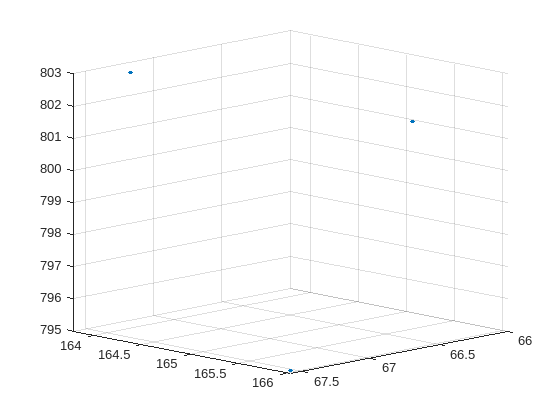


x = filtered2.x;
y = filtered2.y;
z = filtered2.z;

scatter3(x, y, z, marker_size, 'filled')
view([3,3,1])
grid on;